## Getting Shape Data

only first 10 million bp of chr1

write_file = 'chr2_shapes_orchid.txt'

write_file = 'chr2_shapes_orchid.txt'

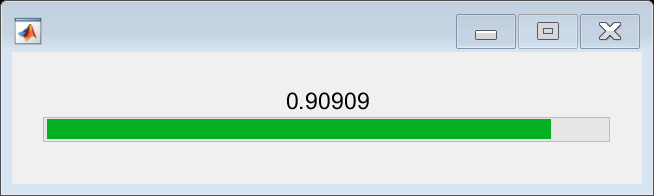

Index in position 2 exceeds array bounds (must not exceed 1).


read_file = fopen('chr2_orchid_output.txt','rt');
regulatory_regions_file = fopen('../RegTfbs/chr2_regTfbs.txt','rt');

output_file = fopen(write_file, 'wt');
fprintf(output_file,'%12s\t %12s\t %12s\n','from', 'to', 'ORCHID');

thisline_reg = fgetl(regulatory_regions_file);
thisline_reg = fgetl(regulatory_regions_file);

thisline_shape = fgetl(read_file);
thisline_shape = fgetl(read_file);

i = 1;
x = 0;
loading = waitbar(0,'Please wait...');
while i < 11000000
    if ~ischar(thisline_reg); break; end  %end of file
    x = x+1;
    C = strsplit(thisline_reg,"\t");
    start = C(1,1);
    stop = C(1,2);
    start = str2double(start{1});
    stop = str2double(stop{1});
    
    if ~ischar(thisline_shape); break; end  %end of file
    line_orchid = strsplit(thisline_shape,"\t");
    n1 = line_orchid(1,2);
    n1 = str2double(n1{1});

    while n1 < start
        i = i+1;
        r = i/11000000;
        progress = round(r,6);
        waitbar(progress,loading,string(progress));
        thisline_shape = fgetl(read_file);
        if ~ischar(thisline_shape); break; end  %end of file
        line_orchid = strsplit(thisline_shape,"\t");
        n1 = line_orchid(1,2);
        n1 = str2double(n1{1});
        n2 = line_orchid(1,3);
        n2 = str2double(n2{1});
    end

    while n2 < stop
        i = i+1;
        r = i/11000000;
        progress = round(r,3);
        waitbar(progress,loading,string(progress));
        line_orchid = strsplit(thisline_shape,"\t");
        n1 = line_orchid(1,2);
        n1 = str2double(n1{1});
        n2 = line_orchid(1,3);
        n2 = str2double(n2{1});
        orchid = line_orchid(1,4);
        orchid = str2double(orchid{1});
        
        fprintf(output_file,'%12d\t %12d\t %12f\n',n1, n2, orchid);
        
        thisline_shape = fgetl(read_file);
        if ~ischar(thisline_shape); break; end  %end of file
    end
    thisline_reg = fgetl(regulatory_regions_file);
end



fclose(regulatory_regions_file);
fclose(read_file);
fclose(output_file);
close(loading)
x

